Consider the following system with 2 dofs


$$\ddot{x}_1+c_1\dot{x}_1+x_1+b_1x_1x_2=\epsilon f_1\cos\Omega t\\\ddot{x}_2+c_2\dot{x}_2+4x_2+b_2x_1^2=\epsilon 
f_2\cos\Omega t$$


It follows that the system has 1:2 internal resonance. Given damping coefficients $c_{1,2}$, nonlinear spring coefficients $b_{1,2}$ and forcing coefficients $f_{1,2}$, the solution manifold of such system is of two dimension and can be parameterized by $(\epsilon,\Omega)$ in general. We use this example to demonstrate

- **SSM_isol2ep**: continuation of equilibrium points in slow-phase normal-form dynamics (corresponding to periodic orbits in the original system) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from an initial solution (isol);

- **SSM_ep2ep**: continuation of equilibrium points in slow-phase reduced dynamics (corresponding to periodic orbits in the original system) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from a saved solution to equilibrium points (ep);

- **SSM_ep2SN**: continuation of saddle-node (SN) bifurcation equilibrium points in slow-phase normal-form dynamics (corresponding to SN bifurcation periodic orbits in the original system) in $(\Omega,\epsilon)$. The continuation here starts from a saved ep solution, which is also a SN equilibrium point;

- **SSM_ep2HB**: continuation of Hopf bifurcation (HB) equilibrium points in slow-phase  normal-form dynamics (corresponding to Neimark-Sacker or torus (TR) bifurcation periodic orbits in the original system) in $(\Omega,\epsilon)$. The continuation here starts from a saved ep solution, which is also a HB equilibrium point;

clear all

## Setup model

m = 1;
c1 = 5e-3;
c2 = 1e-2;
b1 = 1;
b2 = 1;
f1 = 1;
f2 = 0;
[mass,damp,stiff,fnl,fext] = build_model(c1,c2,b1,b2,f1,f2);


DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
epsilon = 1e-2;
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0025 + 1.0000i
  -0.0025 - 1.0000i
  -0.0050 + 2.0000i
  -0.0050 - 2.0000i



## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4]; % choose master spectral subspace
mFreq = [1 2];              % internal resonance relation vector
order = 3;                  % SSM expansion order
outdof = [1 2 3];           % outdof for output

### SSM_epSweeps: continuation of FRC w.r.t $\Omega$ at sampled $\{\epsilon_i\}$

Before diving into the list of functions mentioned above, we demonstrate SSM_epSweeps, a function built based on the SSM_isol2ep and SSM_ep2ep. It

- continues in $\epsilon$ (with fixed $\Omega$) and labels the solutions that satisfies $\epsilon=\epsilon_i$ with UZ,

- continues in $\Omega$ (with $\epsilon\equiv\epsilon_i$) for each $\epsilon_i$,

- plots FRCs

set(S.FRCOptions,'sampStyle', 'cocoBD');                         % sampling style
set(S.contOptions, 'PtMX', 200, 'ItMX', 15, 'h_max', 0.1,'h_min',0.01);    % continuation setting
set(S.FRCOptions, 'nCycle',5000, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.FRCOptions, 'coordinates', 'polar');                       % two coordinate representations

% epsSamp = [0.001 0.005 0.01]
epsSamp = [0.001 0.003 0.005 0.007 0.01]

epsSamp =     0.0010    0.0030    0.0050    0.0070    0.0100


sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.18E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.95E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='sweepseps.

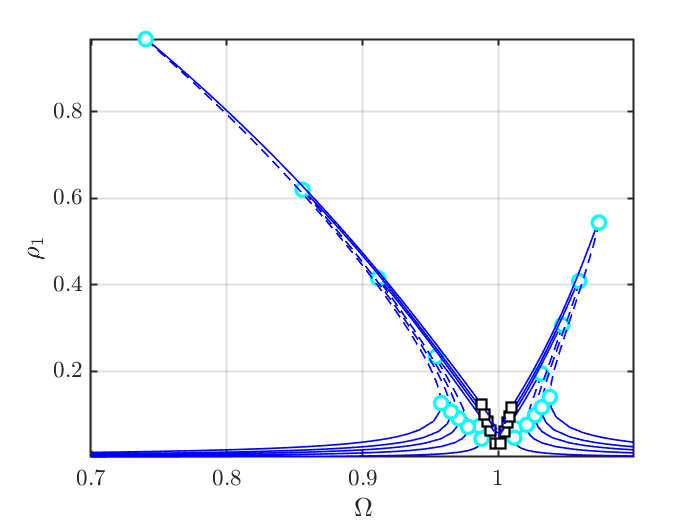

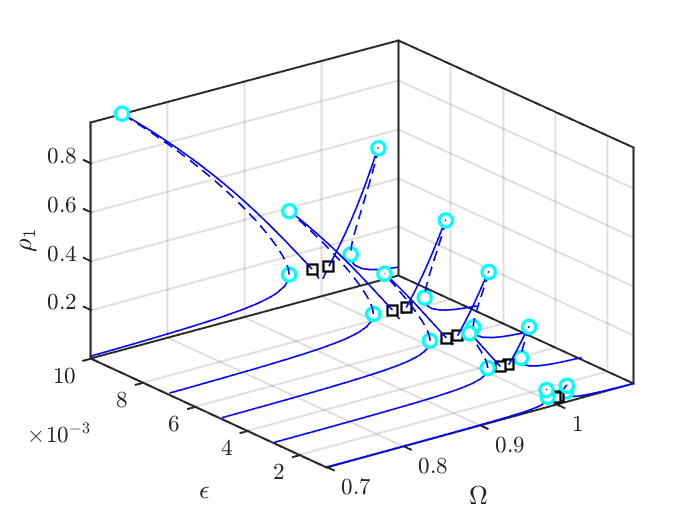

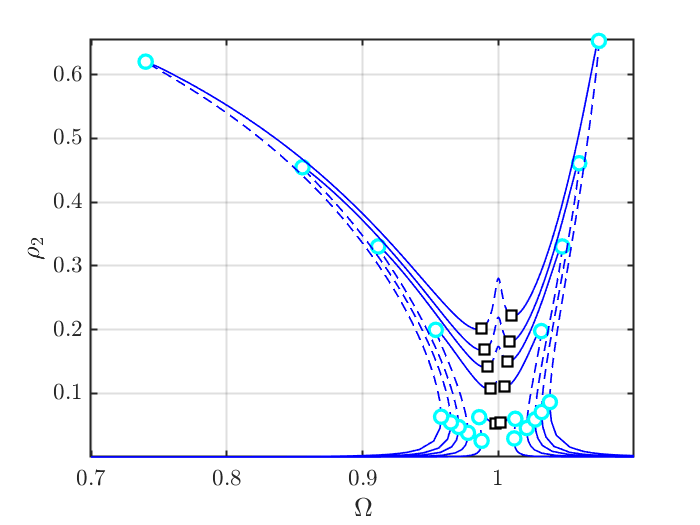

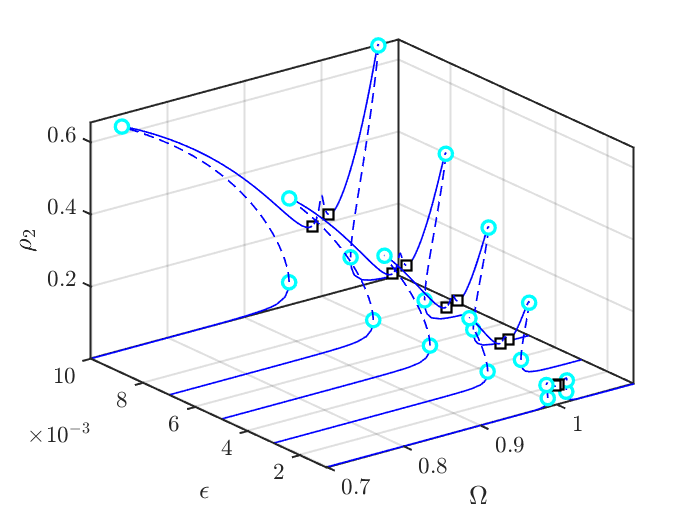

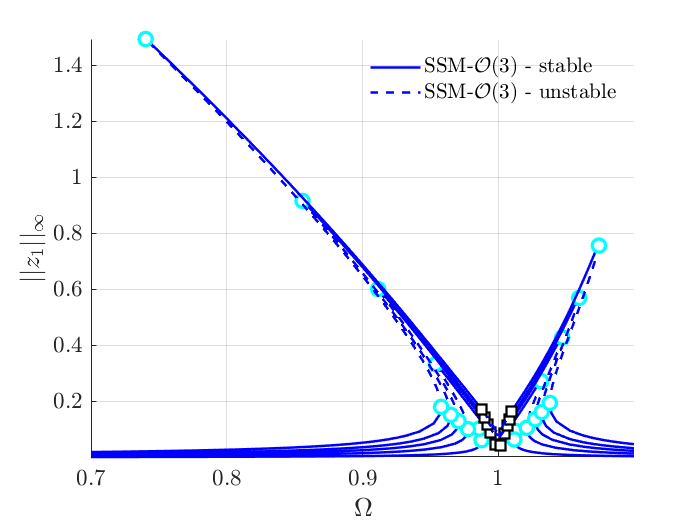

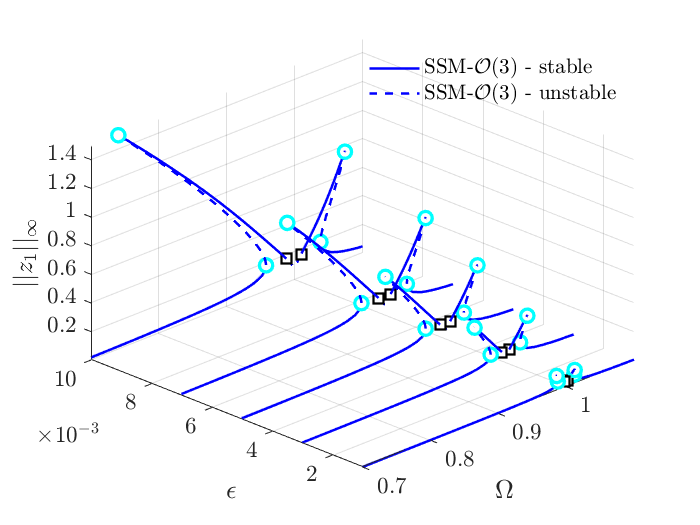

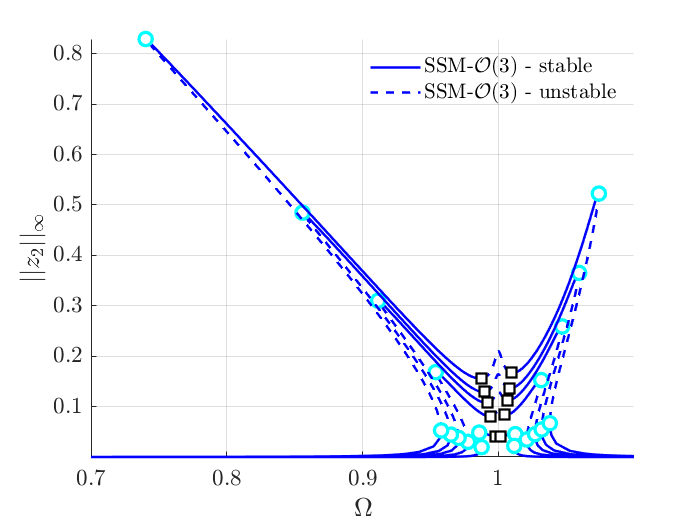

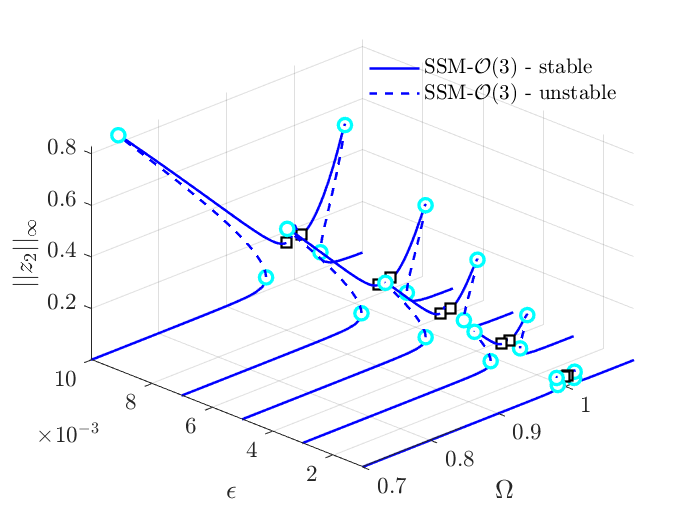

freqRange = [0.7 1.1]*imag(D(1));
S.SSM_epSweeps('sweeps',resonant_modes,order,mFreq,epsSamp,freqRange,outdof);

### **SSM_isol2ep: continuation of equilibrium points from an initial solution**

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.18E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.95E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol_freq.

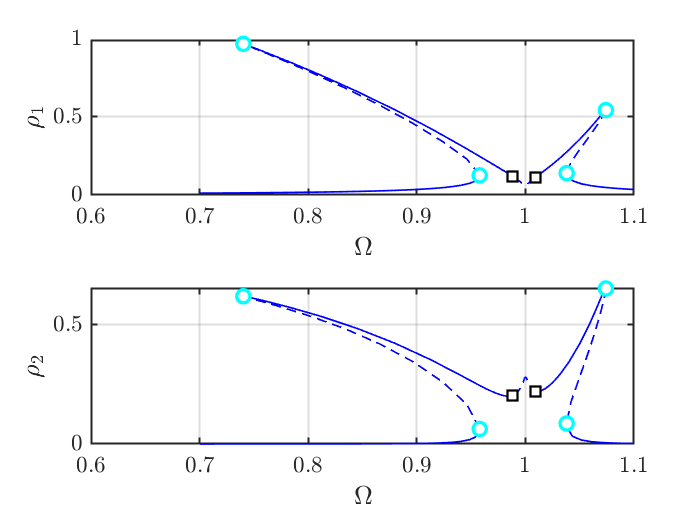

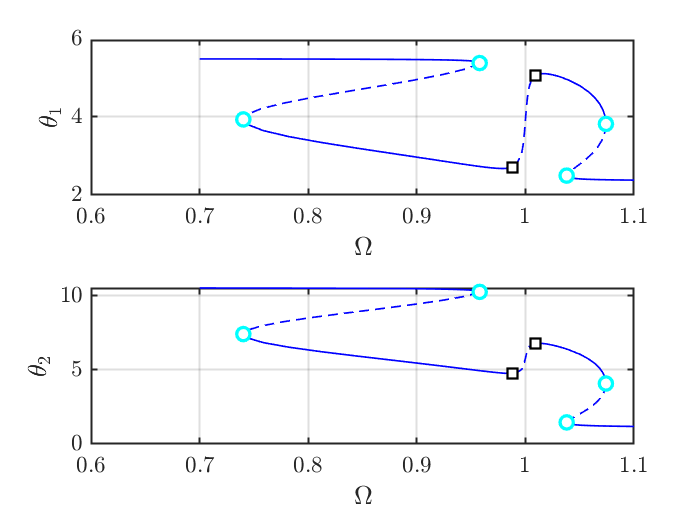

the forcing frequency 7.0000e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.2623e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.5262e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.8029e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.0963e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.3133e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.4822e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.6190e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.7335e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.8322e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

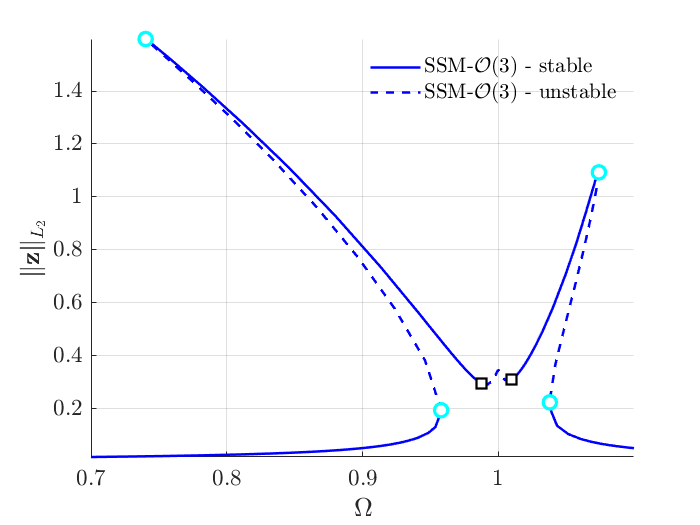

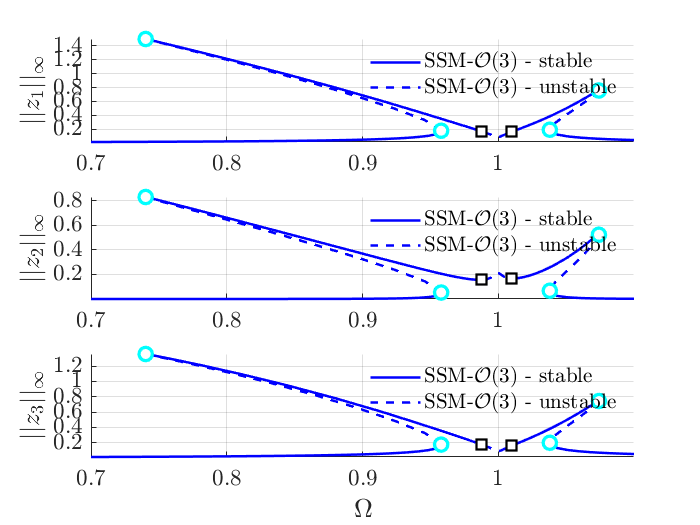

set(S.contOptions, 'PtMX', 200, 'ItMX', 15, 'h_max', 0.5);    % continuation setting
FRC1 = S.SSM_isol2ep('isol_freq',resonant_modes,order,mFreq,'freq',freqRange,outdof);

The above continuation is performed with varied $\Omega$, as indicated by the keyword 'freq'. On the other hand, we may release forcing amplitude $\epsilon$ instead of $\Omega$

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.18E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.95E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol_amp.e

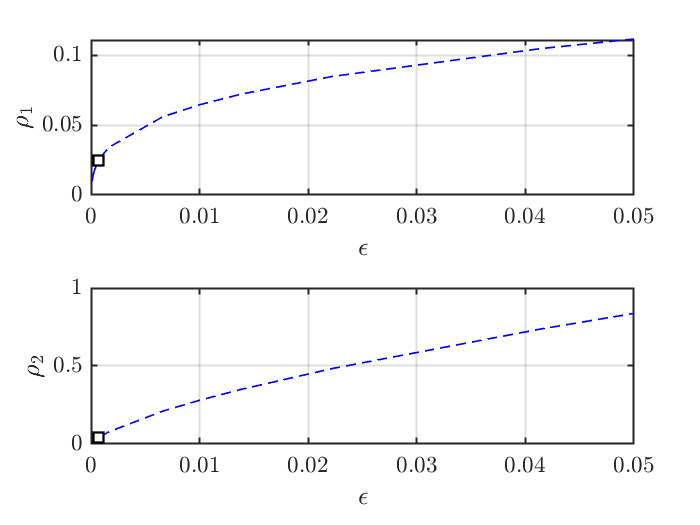

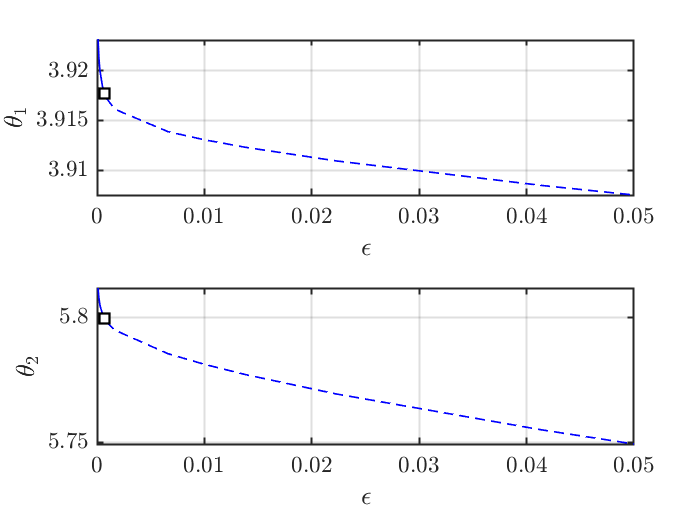

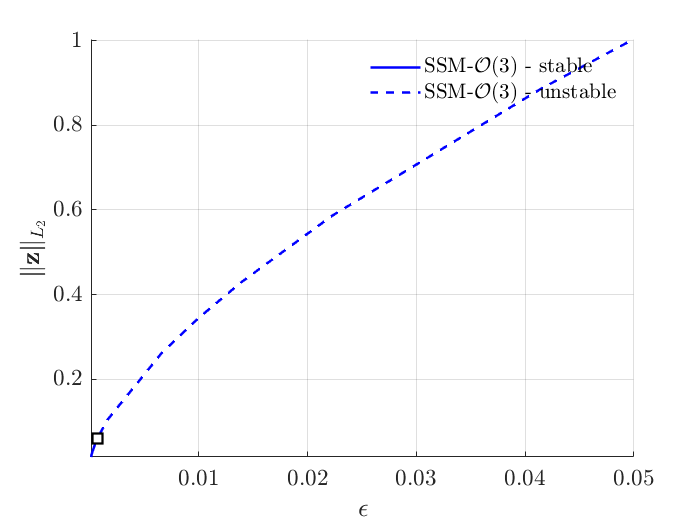

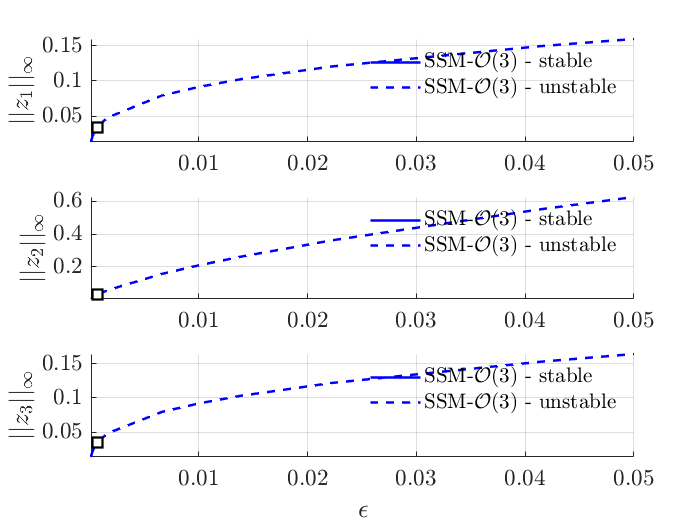

epsRange = [0.01 5]*epsilon;
FRC2 = S.SSM_isol2ep('isol_amp',resonant_modes,order,mFreq,'amp',epsRange,outdof);

### SSM_ep2ep: continuation of equilibrium points from saved solution


 Run='ep.ep': Continue equilibria from label 1 of run isol_freq.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.81e-10  9.93e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps         rho1         rho2          th1          th2           om
    0  00:00:00   9.9315e+00      1  EP      1.0000e-02   6.4627e-02   2.8042e-01   3.9131e+00   5.7812e+00   1.0000e+00
    4  00:00:00   9.9483e+00      2  HB      6.9311e-04   2.4500e-02   4.0295e-02   3.9177e+00   5.7995e+00   1.0000e+00
    8  00:00:00   9.9667e+00      3  EP      9.9158e-05   9.5999e-03   6.1868e-03   3.9232e+00   5.8117e+00   1.0000e+00

 STEP      TIME        ||U||  LABEL  TYPE           eps         rho1         rho2          th1          th2           om
    0  00:00:00   9.9315e+00      4  EP      1.0000e-02   6.4627e-02   2.8042e-01   3.9131e+00   5.7812e+00   1.0000

FRC3 = S.SSM_ep2ep('ep','isol_freq',1,'amp',epsRange,outdof);

### SSM_ep2SN: continuaiton of Saddle-Node bifurcation equilibrium points


 Run='SN.ep': Continue saddle-node equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.07e-07  1.21e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         rho1         rho2          th1          th2
    0  00:00:00   1.2057e+01      1  EP      7.4027e-01   1.0000e-02   9.6886e-01   6.2061e-01   3.9382e+00   7.4030e+00
    2  00:00:00   1.2070e+01      2  EP      7.0000e-01   1.0844e-02   1.0741e+00   6.6133e-01   3.9363e+00   7.4005e+00

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         rho1         rho2          th1          th2
    0  00:00:00   1.2057e+01      3  EP      7.4027e-01   1.0000e-02   9.6886e-01   6.2061e-01   3.9382e+00   7.4030e+00
   10  00:00:00   1.2262e+01      4          9.6408e-01   2.4302e-03   1.8548e-01   1.6132e-01   4.0509e+00   7.5683e+00
   20  00:00:

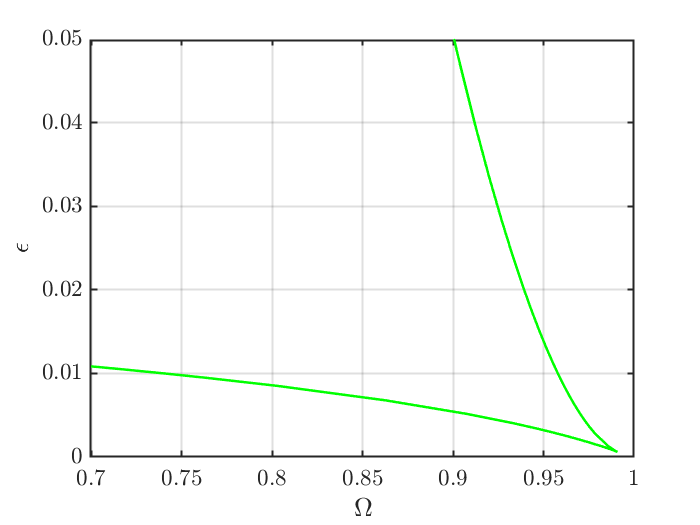

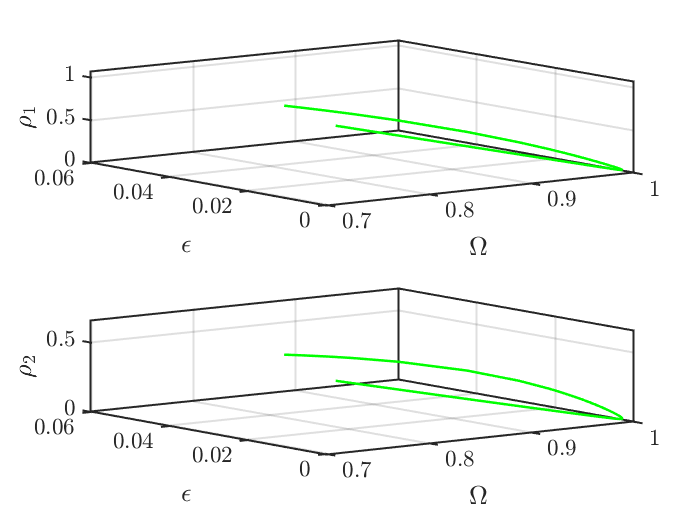

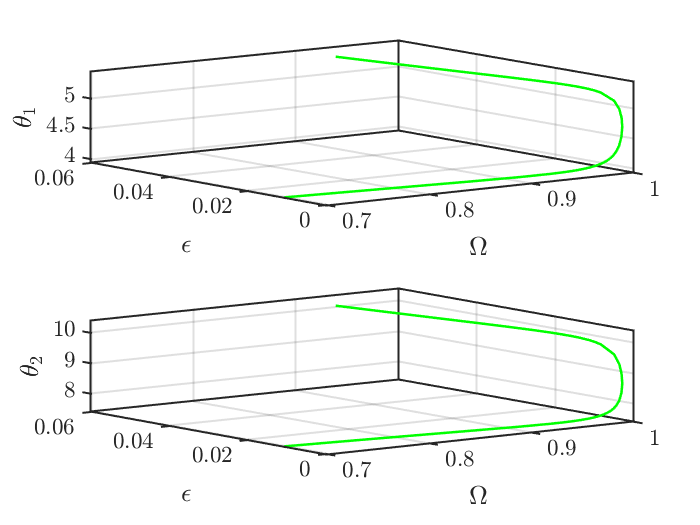

the forcing frequency 7.0000e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.1684e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.4027e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.4027e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.6274e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.0280e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.6326e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.0778e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.3334e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.4531e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

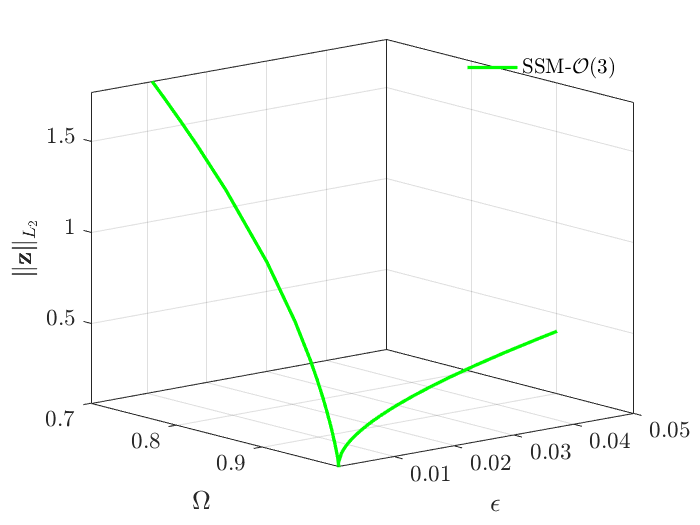

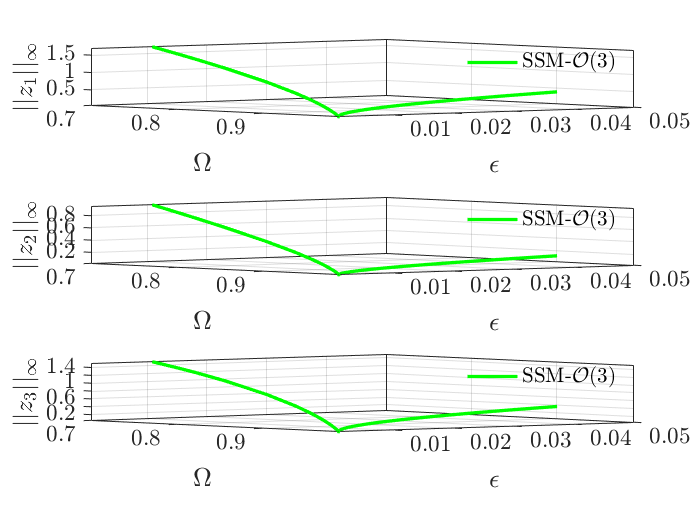

SNlab = 6; % or you use bd=coco_bd_read('isol.ep'); SNlabs=coco_bd_labs(bd, 'SN') to find it
FRC4 = S.SSM_ep2SN('SN','isol_freq',SNlab,{freqRange,epsRange},outdof);

Backbone curve? (view([0,0]) Cusp point

### SSM_ep2HB: continuation of Hopf bifurcation equilibrium points


 Run='HB.ep': Continue Hopf equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.00e-08  7.94e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         rho1         rho2          th1          th2
    0  00:00:00   7.9388e+00      1  EP      9.8785e-01   1.0000e-02   1.2167e-01   2.0189e-01   2.7123e+00   4.7565e+00
    9  00:00:00   7.4546e+00      2  EP      9.6773e-01   5.0000e-02   2.8553e-01   4.2955e-01   2.4981e+00   4.4542e+00

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         rho1         rho2          th1          th2
    0  00:00:00   7.9388e+00      3  EP      9.8785e-01   1.0000e-02   1.2167e-01   2.0189e-01   2.7123e+00   4.7565e+00
   10  00:00:01   9.9193e+00      4          9.9922e-01   7.3680e-04   2.5658e-02   4.2244e-02   3.7633e+00   5.7908e+00
   20  00:00:01   1.

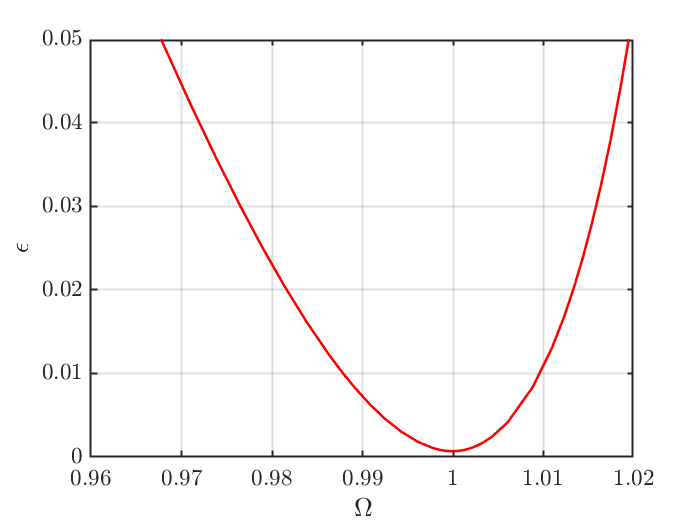

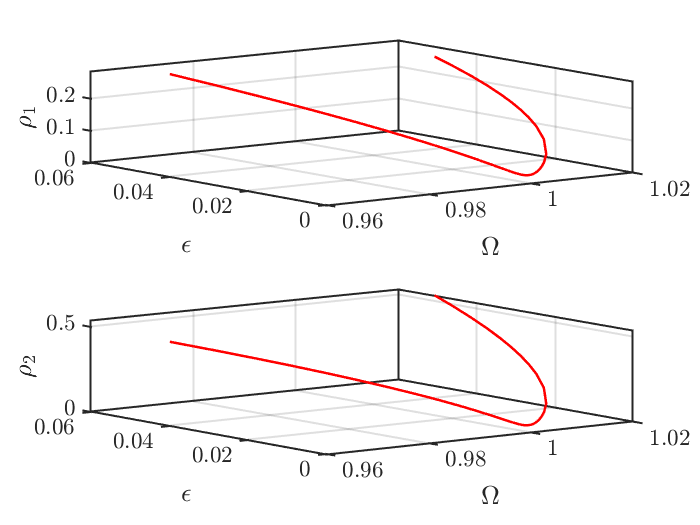

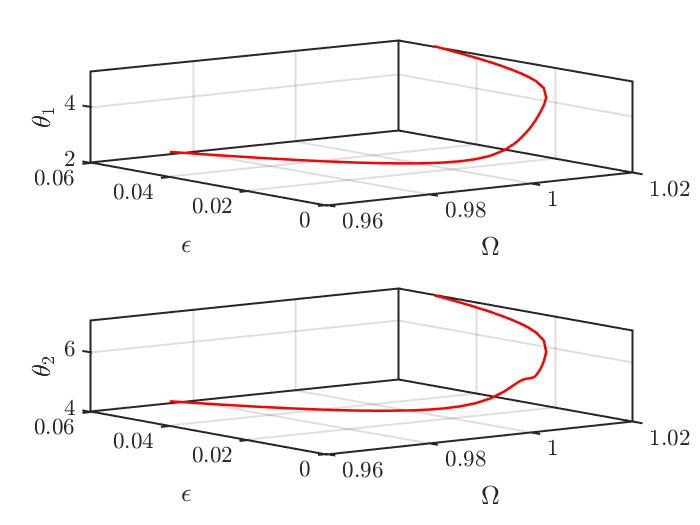

the forcing frequency 9.6773e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.6782e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7105e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7391e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7651e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7895e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8132e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8377e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8625e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8785e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

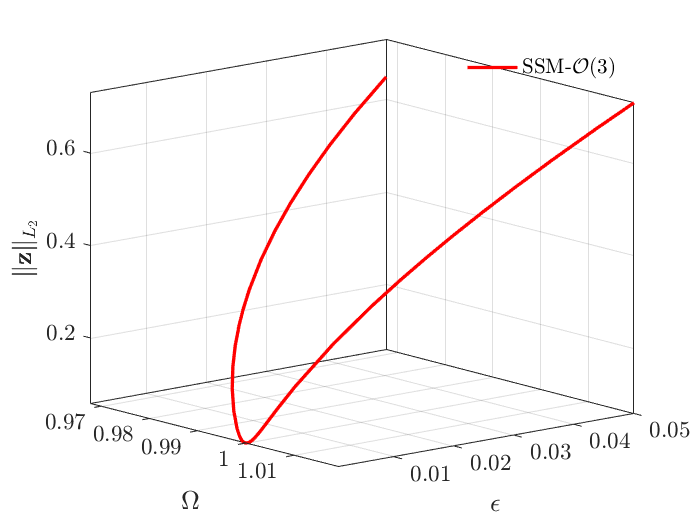

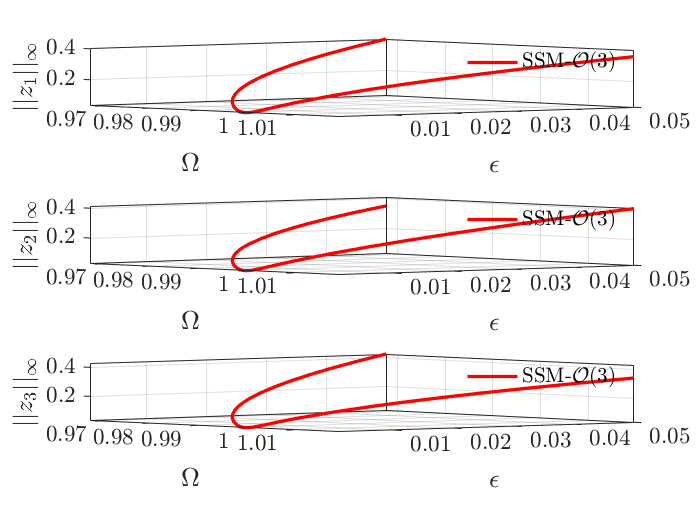

HBlab = 2; % or you use HBlabs = coco_bd_labs(bd, 'HB') to find it
FRC5 = S.SSM_ep2HB('HB','isol_freq',HBlab,{freqRange,epsRange},outdof);

### We consider primary resonnace of the second mode and demonstrate how to use SSM_BP2ep to switch to the secondary branch.

### We use Cartesian coordinates.

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.18E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.95E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol_2ndfr

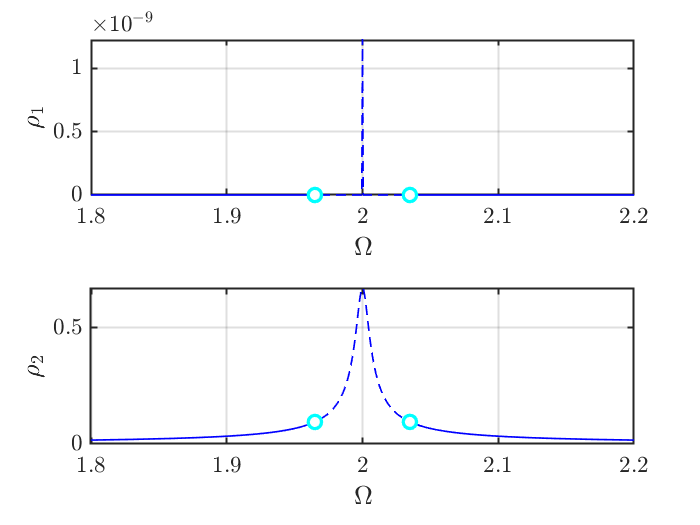

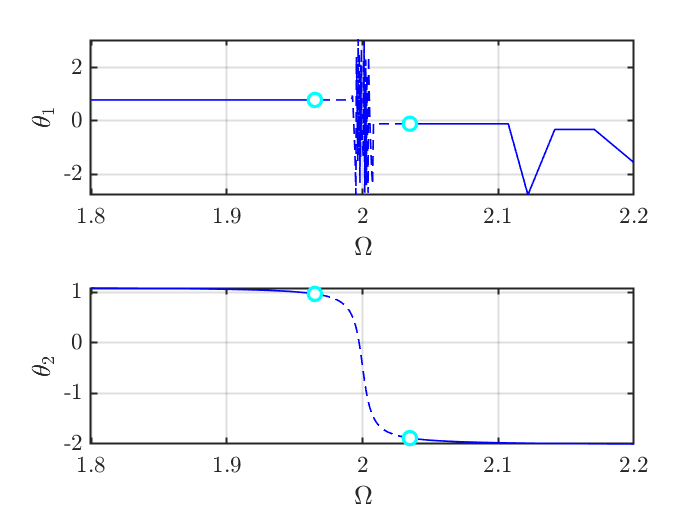

the forcing frequency 1.8000e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.8293e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.8583e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.8781e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.8926e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9038e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9128e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9204e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9269e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9327e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

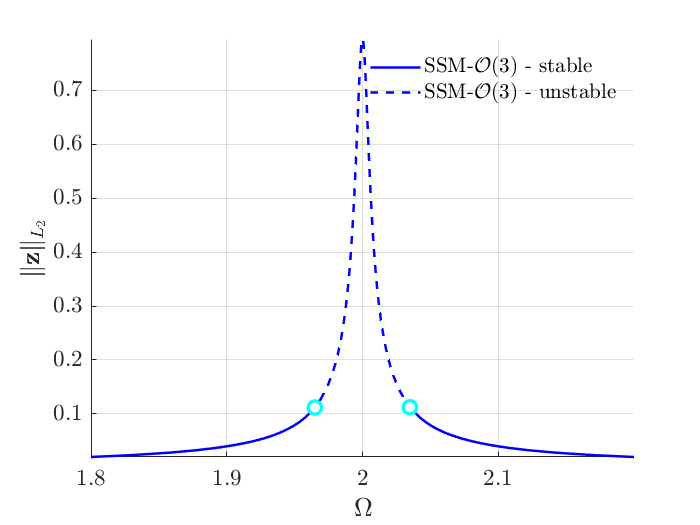

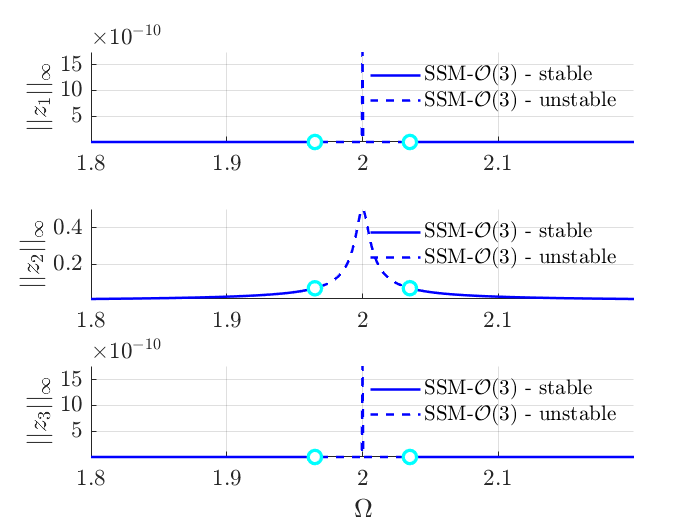

fext = [0;1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);
set(S.FRCOptions,'coordinates','cartesian')
mFreq = [1/2 1];
freqRange = [0.9 1.1]*imag(D(3));
set(S.contOptions, 'PtMX', 150);    % continuation setting
FRC6 = S.SSM_isol2ep('isol_2ndfreq',resonant_modes,order,mFreq,...
    'freq',freqRange,outdof);

### SSM_BP2ep: continuation along the secondary branch


 Run='BPep.ep': Continue equilibria along secondary branch.

 STEP      TIME        ||U||  LABEL  TYPE            om         Rez1         Rez2         Imz1         Imz2          eps
    0  00:00:00   2.7821e+00      1  EP      1.9649e+00  1.9763e-323   5.3903e-02  1.9763e-323   7.7911e-02   1.0000e-02
    1  00:00:00   2.7821e+00      2  BP      1.9649e+00  -1.7779e-09   5.3903e-02  -1.0581e-09   7.7911e-02   1.0000e-02
    1  00:00:00   2.7821e+00      3  SN      1.9649e+00  -4.3485e-08   5.3903e-02  -3.2616e-08   7.7911e-02   1.0000e-02
    1  00:00:00   2.7822e+00      4  FP      1.9650e+00  -1.3633e-03   5.3634e-02  -9.4722e-04   7.7819e-02   1.0000e-02
   10  00:00:00   2.7622e+00      5          1.9450e+00  -9.6279e-02   9.8501e-02  -6.1342e-02   9.5319e-02   1.0000e-02
   20  00:00:00   2.7178e+00      6          1.8870e+00  -2.5905e-01   2.3518e-01  -8.4766e-02   5.3707e-02   1.0000e-02
   30  00:00:01   2.7018e+00      7          1.8583e+00  -3.3935e-01   2.7621e-01  -3.2268e

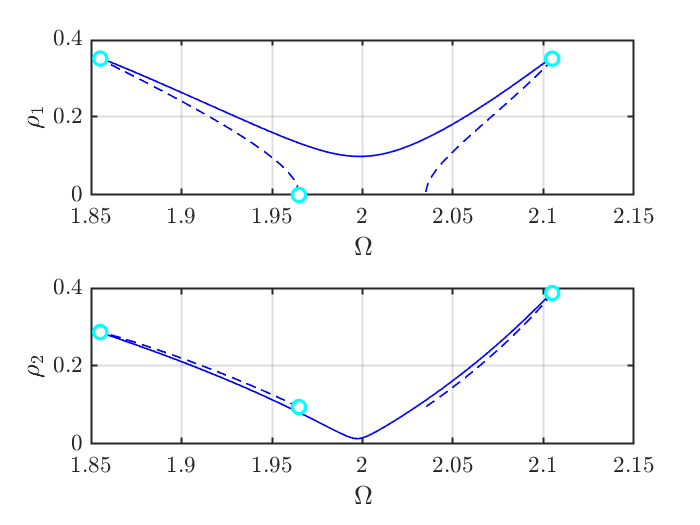

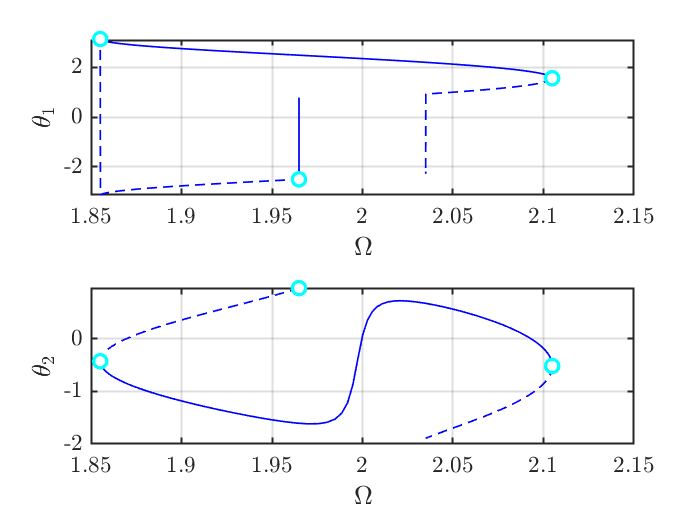

the forcing frequency 1.9649e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9649e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9649e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9650e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9648e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9645e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9639e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9630e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9617e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.9599e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

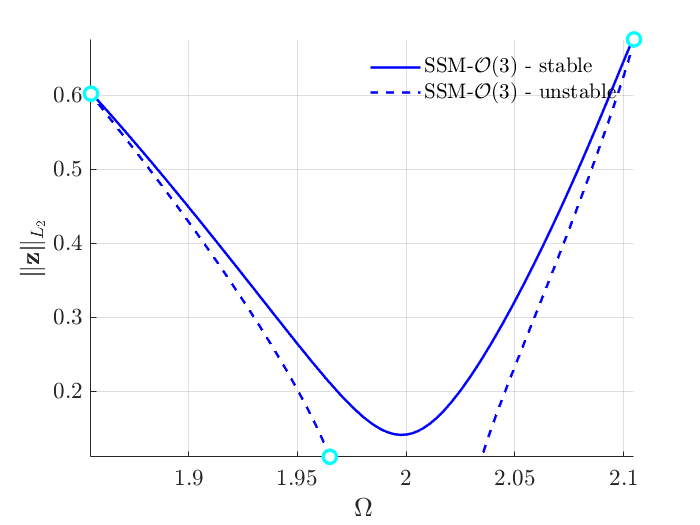

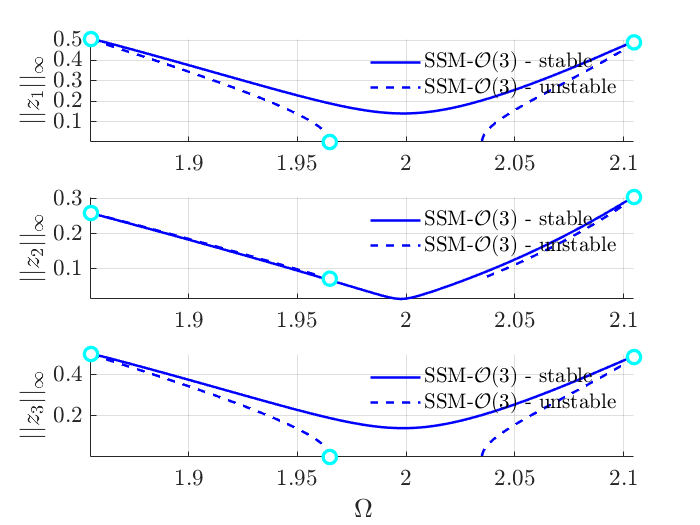

BPlab = 6;
set(S.contOptions,'bi_direct',false)
FRC6_BP = S.SSM_BP2ep('BPep','isol_2ndfreq',BPlab,'freq',freqRange,outdof);